# Full Wave Simulator

Converts LTSPICE .txt files to a MATLAB Matrix and plots

## Directory and Internal Libraries/Functions

Sets paths easily to run, calling functions that import different data types

computer = "PC"

computer = "PC"

if (strcmp(computer, 'PC')) % PC
    %cd 'G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0';
    cd 'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1'
    addpath( 'G:\My Drive\Code\LTSpice\200825 xGAN xGEM Load Responses V1\', ...  % LT Spice output response
        'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1',...
        'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter', ... % LT Spice reader from Github
        'C:\Users\johns\Documents\Github\QEM-MATLAB', ...    % Access to generic libraries
        'G:\My Drive\Code\COMSOL\xGAN Gated Mirror Sims\Other Structures\inductor_export\'); %new comsol stuff
    
elseif (strcmp(computer, 'Mac'))
    %cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter'
    addpath('/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/QEM-MATLAB/Data Converters/LTSpice_Converter', ...
        '/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/QEM-MATLAB', ...
        '/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/Gated-Mirror_xGANxSCAxGEM/200801 xGAN Full Module v1');
end

load('ImpVariables.mat')

## Generate and Fit Impedance Response of Load

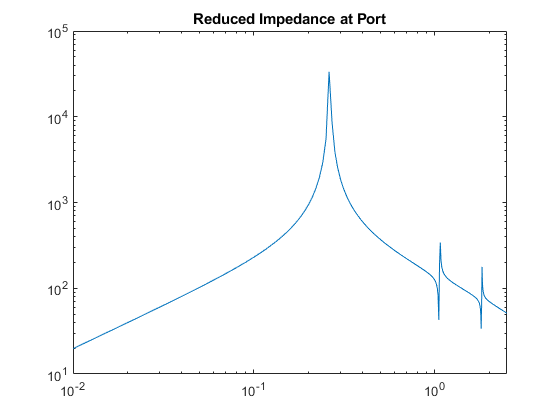

% Workbook for impedance math in "C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1"
% Result is plotted
clf
% port = ImportCOMSOL_Z('PortTo9p76Ghz.txt');
% yyaxis left
% loglog(port.freq, abs(port.z))
% yyaxis right
% semilogx(port.freq, unwrap(angle(port.z)),'LineStyle',"--");
% title('Impedance at Port')
% hold off

% Range seems to large, shrinking to 5GHz...
numPortPts = 250;
portRedFreq = port.freq(1:numPortPts); 
portRedS11 = port.s11(1:numPortPts); 
portRedZ = port.z(1:numPortPts);
loglog(portRedFreq, abs(portRedZ))
title('Reduced Impedance at Port')
hold off 


ratFitS = rationalfit(portRedFreq, portRedS11);
generateSPICE(ratFitS, 'JWS_InductorRed_v2.ckt');


## Check Converted Impedance Response 

**IMPORTING  -** Two Columns, Export using Log Scale (Ohm) and [f, Re1, Im1, Re2, Im2] parts

clf
figure()
filenameAdd = '200825 xGAN xGEM Freq Response.txt';
freqSample = 10;

Data = LT_Freq2Table(filenameAdd);
Data = table2array(Data);
Data = str2double(Data);

FreqSweepVect = Data(:,1);
Re1 = Data(:,2);
Im1 = Data(:,3);
Z1 = (Re1.^2 + Im1.^2).^0.5;
Re2 = Data(:,4);
Im2 = Data(:,5);
Z2 = (Re2.^2 + Im2.^2).^0.5;


loglog(port.freq, abs(port.z), 'LineWidth', 1.5) %, 'Color', 'black')
set(gcf, 'Position', [0 0 400 300]);
hold on
%loglog(FreqSweepVect, Z1, 'LineStyle',"--") %, 'Color', 'black')
loglog(FreqSweepVect, Z2, "LineStyle","--") %, 'Color', 'black')
title('Impedance of Load and RLC Equivalent')
ylabel({'Impedance Magnitude (\Omega)'});
xlabel({'Frequency (Hz)'});
legend('Full Impedance Response', 'RLC Approximate Response', 'Fit Impedance Response', 'Location', 'northwest')

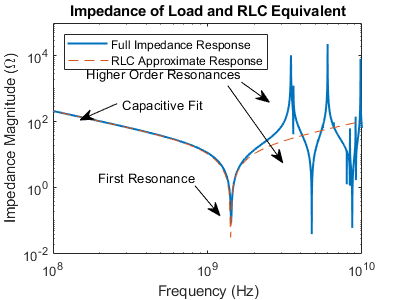

xlim([1e8,1e10])
ylim([1e-2 1e5])
annotation('arrow',[0.5696 0.7071],[0.7143 0.4571])
annotation('textarrow',[0.6036 0.6732],[0.7262 0.6595],'String','Higher Order Resonances')
annotation('textarrow',[0.4875 0.55],[0.3809 0.2809],'String','First Resonance')
annotation('textarrow',[0.2929 0.2],[0.6548 0.6],'String','Capacitive Fit')
hold off

C_eff = 1/(2*pi*port.freq(freqSample)*abs(port.z(freqSample)))

C_eff = 7.3984e-12


resFreq = 1.42e9; %GHz
% w^2 = 1/LC
L_eff = 1/((2*pi*resFreq)^2*C_eff)

L_eff = 1.6980e-09

## Convert COMSOL Transfer Function 

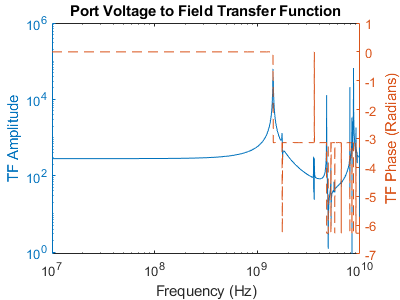

filename='TransferFnTo9p76GHz.txt';
makeSymmetric = 1;
[rawTF, symTF] = ImportCOMSOL_TF(filename, port.v, makeSymmetric);

clf;
% Look at transfer Function
yyaxis left
loglog(rawTF.freq,abs(rawTF.fieldTF)); ylabel("TF Amplitude");
yyaxis right
semilogx(rawTF.freq, unwrap(angle(rawTF.fieldTF)),'LineStyle',"--"); ylabel("TF Phase (Radians)"); xlabel("Frequency (Hz)");
title("Port Voltage to Field Transfer Function");
hold off

## Time Domain Constant step exporter

Takes data from batch files in LTSpice and exports

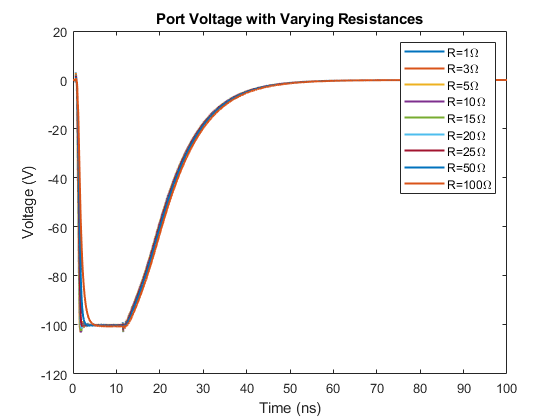

name = '200825 xGAN Kimball Circuit Resetting.txt';
timeRes = 1/20e9; % 20GHz total BW (10Ghz positive)
interpMethod = 'linear'; %pchip linear
[stepR,interpTime, interpVoltAll] = ImportLTSpiceSweep(name, timeRes, interpMethod);
% ADD LTSPICE SIM NOTES

% Plots out result read from file to check
figure()
plot(interpTime/c.nano, interpVoltAll, "LineWidth", 1.5); xlabel('Time (ns)'); ylabel('Voltage (V)'); title('Port Voltage with Varying Resistances')
rNames = string(stepR);
legend('R=' + rNames +'\Omega')

%xlim([0 10])
save("200825 xGAN Kimball Circuit Resetting.mat", "stepR", "interpTime", "interpVoltAll");

## Generate and Plot LTSpice Output FT

% clf;

% [time, signal, freq, fftSignal] = inputFunction('gEdge', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:),100e15);
% plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("LTSpice Port Voltage")
% %xlim([0,10])
% 
% %Compares steps
% % for resIndexTemp = 1:9
% %     [time, signal, freq, fftSignal] = inputFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndexTemp,:));
% %     loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1)/abs(fftSignal(1)))); 
% %     xlabel("Frequency"); ylabel("Amplitude"); title('Pulse in Frequency Domain')
% %     hold on
% % end
% % xlim([5e8 1e10])
% % hold off


## Combine and Plot Output

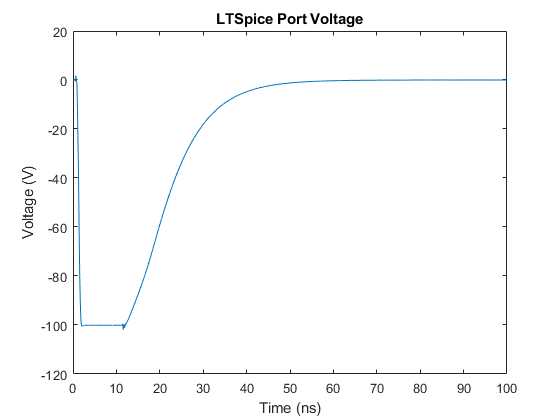

clf
resIndex = 7;
%tiledlayout(2,2);
stepR(resIndex);
[time, signal, freq, fftSignal] = inputFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:),0, 0);
% Plot Original Time
plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("LTSpice Port Voltage")

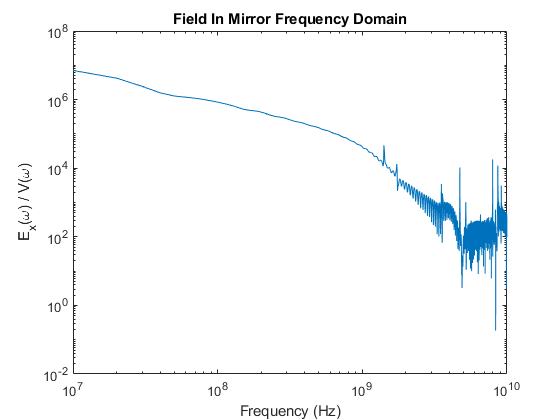


% Plot FFT Original
% loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1))); title('Port Voltage Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('Port Voltage (V)')

% Plot Mixed Signal
outputFFT = fftSignal.*symTF.fieldTF;
loglog(freq((end-1)/2+1:end), abs(outputFFT(2:(end+1)/2+1))); title('Field In Mirror Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('E_x(\omega) / V(\omega)')

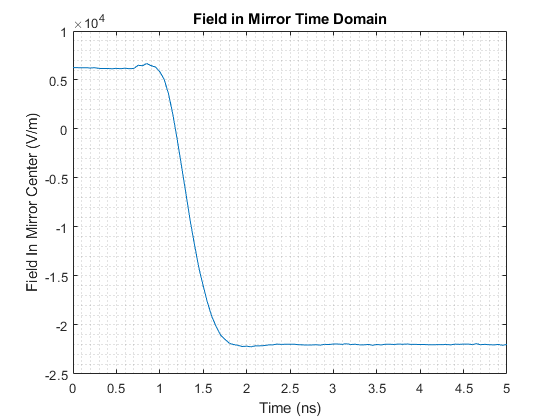


% Plot Final Result
outputSignal = ifft(outputFFT); 
plot(time/c.nano, outputSignal);%, [-50 50], [0.5 0.5], '--', [-50 50], [0.005 0.005], '--');
title('Field in Mirror Time Domain'); xlabel("Time (ns)"); ylabel("Field In Mirror Center (V/m)");
grid minor;
xlim([0,5])

## Plot Multiple Outputs

%Compares steps
clf;
%SelectedTraces = [1, 10, 25, 50]
%outputSignalAll = zeros(9,2001);
for resIndexTemp = 1:9
    [time, signal, freq, fftSignal] = inputFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndexTemp,:), 0, 0);
    
    outputFFT = fftSignal.*symTF.fieldTF;
    outputSignalAll(resIndexTemp,:) = ifft(outputFFT); 
end
outputSignalRescaled = (outputSignalAll-outputSignalAll(1,1))/outputSignalAll(1,1)*0.22;
plot(time/c.nano, outputSignalRescaled, 'LineWidth',1.5);
%title('Field in Mirror Time Domain'); 
xlabel("Time (ns)"); ylabel("Scaled Field in Mirror (V/m)");
legend('R_{damp} = ' + rNames +'\Omega')
%legend("Ideal Gaussian Response")
xlim([0,5])
%ylim([-1.1, -0.9])


## Plot Error Function (Ideal) Response

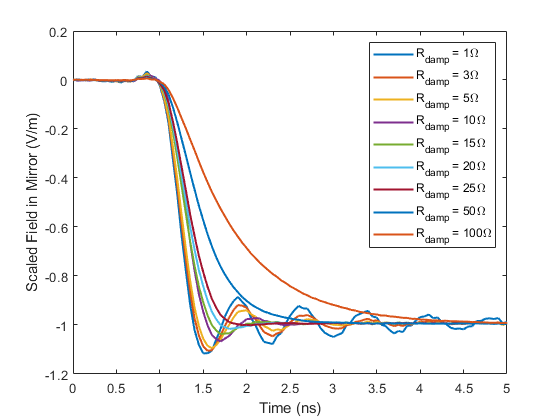

clf

resIndex = 7;
%tiledlayout(2,2);
stepR(resIndex);
[time, signal, freq, fftSignal] = inputFunction('Custom', 1/20e9, 10*c.mega,  interpTime, interpVoltAll(resIndex,:),10.05, 0);
% Plot Original Time
plot(time/c.nano, signal); xlabel("Time (ns)"); ylabel("Voltage (V)"); title("LTSpice Port Voltage")

% Plot FFT Original
% loglog(freq((end-1)/2+1:end), abs(fftSignal(2:(end+1)/2+1))); title('Port Voltage Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('Port Voltage (V)')

% Plot Mixed Signal
outputFFT = fftSignal.*symTF.fieldTF;
loglog(freq((end-1)/2+1:end), abs(outputFFT(2:(end+1)/2+1))); title('Field In Mirror Frequency Domain'); xlabel('Frequency (Hz)'); ylabel('E_x(\omega) / V(\omega)')

% Plot Final Result
outputSignal = ifft(outputFFT); 
outputSignalRescaled = ((outputSignal/280/2)+0.50367)/1.007; %(outputSignal-outputSignal(1,1))/outputSignal(1,1)/2;
plot(time/c.nano, outputSignalRescaled);%, [-50 50], [0.5 0.5], '--', [-50 50], [0.005 0.005], '--');
title('Field in Mirror Time Domain'); xlabel("Time (ns)"); ylabel("Field In Mirror Center (V/m)");
grid minor;
xlim([0,5])
%erfOutput = outputSignalRescaled-1;
%erfTime = time;
%ylim([0 0.01])